# Exam January 11, 2019

## Exercise 1

clear

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

q = sym('q',[1 4])

$$q = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

syms d1 a4 L
dh = [ pi/2 0 d1 q(1);
       pi/2 0 0 q(2);
       pi/2 0 q(3) pi;
       0 a4 0 q(4)]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & d_{1} & q_{1}\\ \frac{\pi }{2} & 0 & 0 & q_{2}\\ \frac{\pi }{2} & 0 & q_{3} & \pi \\ 0 & a_{4} & 0 & q_{4} \end{array}\right)$$


[T Tpartial] = getTransformationMatrix(dh,'alpha')

$$T = \begin{array}{l} \left(\begin{array}{cccc} -\cos\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sigma_{1}\\ -\cos\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{2}+q_{4}\right) & -\cos\left(q_{2}+q_{4}\right) & 0 & d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right) \end{array}$$

Tpartial = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}



P = T(1:3,4)

$$P = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

q0 = [0  pi/2 L 0]

$$q0 = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & L & 0 \end{array}\right)$$

P4_0 = subs(P,q,q0)

$$P4\_0 = \left(\begin{array}{c} L\\ 0\\ d_{1}-a_{4} \end{array}\right)$$

close all
% Lengths just to test
len = 20

len = 20

len1 = 10

len1 = 10

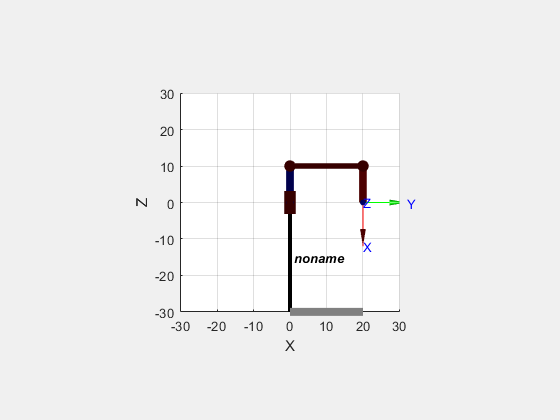

% De Luca's approach
links = [
    Revolute('a', 0, 'alpha', pi/2 ,'d', len1);
    Revolute('a', 0, 'alpha', pi/2 ,'d', 0);
    Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
    Revolute('a', len1, 'alpha', 0 ,'d', 0);
    ];

c600 = SerialLink(links);
%c600.teach([0  pi/2 10 0],'view','x')
c600.plot([0  pi/2 20 0],'view','x')

% My original approach --> Not the same result
close all
len = 20

len = 20

len1 = 10

len1 = 10

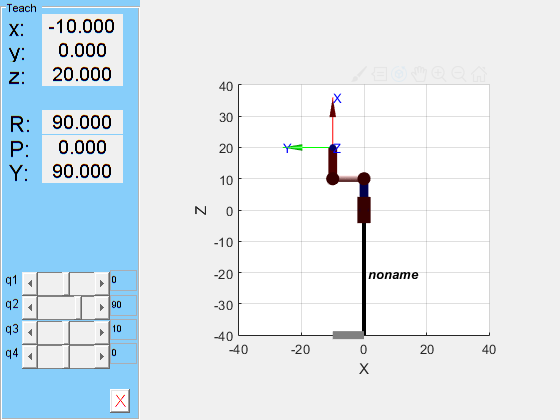

links = [
    Revolute('a', 0, 'alpha', pi/2 ,'d', len1);
    Revolute('a', 0, 'alpha', -pi/2 ,'d', 0);
    Prismatic('qlim', [0 len],'alpha',pi/2,'theta',0);
    Revolute('a', len1, 'alpha', 0 ,'d', 0);
    ];

c600 = SerialLink(links);
c600.teach([0  pi/2 10 0],'view','x')

%c600.plot([0  pi/2 10 0],'view','x')

## Exercise 2

[Jp Jo] = getJacobian(dh,'RRPR','alpha')

$$Jp = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(q_{1}\right)\,\sigma_{2} & \cos\left(q_{1}\right)\,\sigma_{1} & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{4}\,\sin\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right)\,\sigma_{2} & \sin\left(q_{1}\right)\,\sigma_{1} & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{4}\,\sin\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right)\\ 0 & q_{3}\,\sin\left(q_{2}\right)-\sigma_{3} & -\cos\left(q_{2}\right) & -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\sin\left(q_{2}+q_{4}\right)+q_{3}\,\cos\left(q_{2}\right)\\ \sigma_{2}=\sigma_{3}-q_{3}\,\sin\left(q_{2}\right)\\ \sigma_{3}=a_{4}\,\cos\left(q_{2}+q_{4}\right) \end{array}$$

$$Jo = \left(\begin{array}{cccc} 0 & \sin\left(q_{1}\right) & 0 & \sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)$$


rank(Jo)

ans = 2

%The generic rank of the lower Jac matrix is 2
J = [Jp;Jo];
J0 = subs(J,q,q0)

$$J0 = \left(\begin{array}{cccc} 0 & a_{4} & 1 & a_{4}\\ L & 0 & 0 & 0\\ 0 & L & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & -1 & 0 & -1\\ 1 & 0 & 0 & 0 \end{array}\right)$$

Jp0 = subs(Jp,q,q0)

$$Jp0 = \left(\begin{array}{cccc} 0 & a_{4} & 1 & a_{4}\\ L & 0 & 0 & 0\\ 0 & L & 0 & 0 \end{array}\right)$$

qdot = sym('q',[4,1])

$$qdot = \left(\begin{array}{c} q_{1}\\ q_{2}\\ q_{3}\\ q_{4} \end{array}\right)$$

JpQdot = Jp0*qdot

$$JpQdot = \left(\begin{array}{c} q_{3}+a_{4}\,q_{2}+a_{4}\,q_{4}\\ L\,q_{1}\\ L\,q_{2} \end{array}\right)$$

[qdot01 qdot02 qdot03 qdot04] = solve(JpQdot == 0,qdot)

$$qdot01 = 0$$

$$qdot02 = 0$$

$$qdot03 = 0$$

$$qdot04 = 0$$

v1 = [1 0 1];
w1 = [0 0 -2];
V = [v1  w1]

V =      1     0     1     0     0    -2



[qdot1 qdot2 qdot3 qdot4] = solve(JpQdot == v1.')

$$qdot1 = 0$$

$$qdot2 = \frac{1}{L}$$

$$qdot3 = \frac{L-a_{4}}{L}$$

$$qdot4 = 0$$

null(JpQdot-v1)

$$ans = \left(\begin{array}{c} -1\\ 0\\ 1 \end{array}\right)$$

%It is not possible to satisfy both v and w conditions
[qdot1 qdot2 qdot3 qdot4] = solve(J0*qdot == V)

 
qdot1 =
 
Empty sym: 0-by-1
 
 
qdot2 =
 
Empty sym: 0-by-1
 
 
qdot3 =
 
Empty sym: 0-by-1
 
 
qdot4 =
 
Empty sym: 0-by-1
 


J0.'

$$ans = \left(\begin{array}{cccccc} 0 & L & 0 & 0 & 0 & 1\\ a_{4} & 0 & L & 0 & -1 & 0\\ 1 & 0 & 0 & 0 & 0 & 0\\ a_{4} & 0 & 0 & 0 & -1 & 0 \end{array}\right)$$

tau = J0.'*Fc

$$tau = \left(\begin{array}{cc} {\mathrm{Fc}}_{6,1}+{\mathrm{Fc}}_{2,1}\,L & {\mathrm{Fc}}_{6,2}+{\mathrm{Fc}}_{2,2}\,L\\ {\mathrm{Fc}}_{1,1}\,a_{4}-{\mathrm{Fc}}_{5,1}+{\mathrm{Fc}}_{3,1}\,L & {\mathrm{Fc}}_{1,2}\,a_{4}-{\mathrm{Fc}}_{5,2}+{\mathrm{Fc}}_{3,2}\,L\\ {\mathrm{Fc}}_{1,1} & {\mathrm{Fc}}_{1,2}\\ {\mathrm{Fc}}_{1,1}\,a_{4}-{\mathrm{Fc}}_{5,1} & {\mathrm{Fc}}_{1,2}\,a_{4}-{\mathrm{Fc}}_{5,2} \end{array}\right)$$

null(J0.')

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & -\frac{1}{L}\\ 0 & 0\\ 1 & 0\\ 0 & 0\\ 0 & 1 \end{array}\right)$$

## Exercise 3

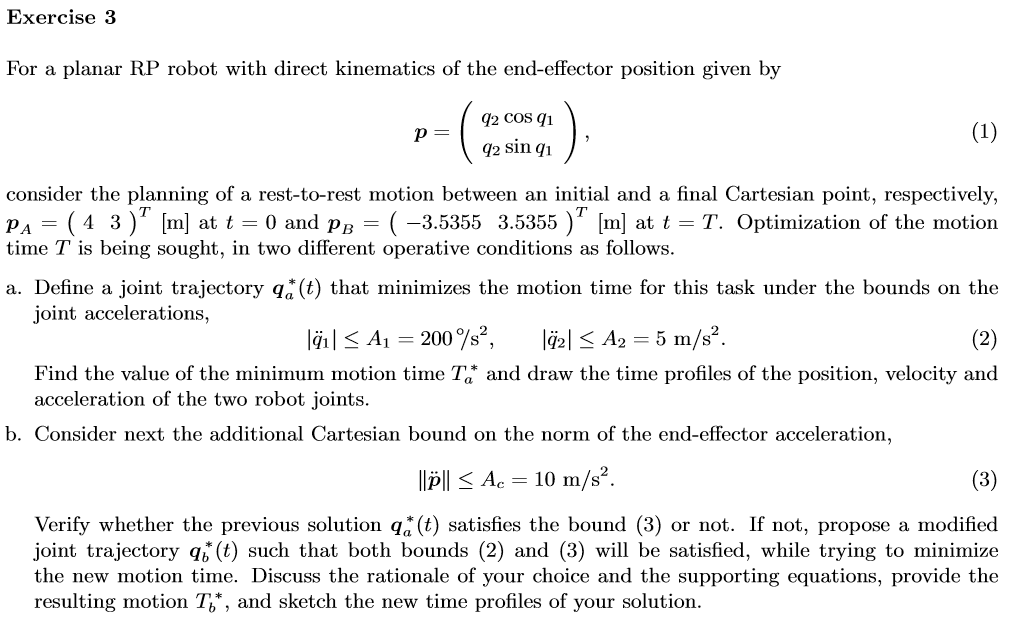

q = sym('q',[2,1])

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

p = [q(2)*cos(q(1)); q(2)*sin(q(1))]

$$p = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

pa = [4;3];
pb = [-3.5355 ;3.5355];

[q_a1 q_a2 ] = solve(p == pa, q);
eval([180/pi*q_a1 q_a2 ]);
[q_b1 q_b2 ] = solve(p == pb, q);
eval([180/pi*q_b1 q_b2 ]);

%We choose the solution with positive q2
pick = 2;
qA = eval([q_a1(pick); q_a2(pick)])

qA =     0.6435
    5.0000


qB = eval([q_b1(pick); q_b2(pick)])

qB =     2.3562
    5.0000


syms q0 q1 v0 v1 t T a b c tao dq 

% Declare equation system for joint space trajectory

eq(1) = a+b+c == 1;
eq(2) = c == v0*T/dq;
eq(3) = 3*a+2*b+c == v1*T/dq;
eq.';
[as,bs,cs]=solve(eq.',[a b c])

$$as = \frac{T\,v_{0}}{\mathrm{dq}}+\frac{T\,v_{1}}{\mathrm{dq}}-2$$

$$bs = 3-\frac{T\,v_{1}}{\mathrm{dq}}-\frac{2\,T\,v_{0}}{\mathrm{dq}}$$

$$cs = \frac{T\,v_{0}}{\mathrm{dq}}$$


qd = q0 + dq*(as*tao^3 + bs*tao^2 + cs*tao)

$$qd = q_{0}+\mathrm{dq}\,\left({\mathrm{tao}}^{3}\,\left(\frac{T\,v_{0}}{\mathrm{dq}}+\frac{T\,v_{1}}{\mathrm{dq}}-2\right)-{\mathrm{tao}}^{2}\,\left(\frac{2\,T\,v_{0}}{\mathrm{dq}}+\frac{T\,v_{1}}{\mathrm{dq}}-3\right)+\frac{T\,\mathrm{tao}\,v_{0}}{\mathrm{dq}}\right)$$


qa = subs(qd,[dq tao],[q1-q0 t/T])

$$qa = q_{0}+\left(q_{0}-q_{1}\right)\,\left(\frac{t\,v_{0}}{q_{0}-q_{1}}+\frac{t^{3}\,\left(\frac{T\,v_{0}}{q_{0}-q_{1}}+\frac{T\,v_{1}}{q_{0}-q_{1}}+2\right)}{T^{3}}-\frac{t^{2}\,\left(\frac{2\,T\,v_{0}}{q_{0}-q_{1}}+\frac{T\,v_{1}}{q_{0}-q_{1}}+3\right)}{T^{2}}\right)$$

qa = subs(qa,[v0 v1],[0 0])

$$qa = q_{0}-\left(\frac{3\,t^{2}}{T^{2}}-\frac{2\,t^{3}}{T^{3}}\right)\,\left(q_{0}-q_{1}\right)$$


%Initial conditions
% w is omega, for angular velocity
% acc is angular acceleration
w = diff(qa,t)

$$w = -\left(q_{0}-q_{1}\right)\,\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right)$$

acc = diff(w,t)

$$acc = \left(q_{0}-q_{1}\right)\,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right)$$


%w0 = subs(w,t,0)
%wT = subs(w,t,T)

%acc0 = subs(acc,t,0)
%jerk = diff(acc,t)

%Evaluate the expression with the initial and final joint values
%The f subscript is used to differenciate a from the point. q_a = f

acc_f = subs(acc,[q0 q1],[qA(1) qB(1)])

$$acc\_f = -\left(\frac{3\,\pi }{4}-\frac{5796142707547873}{9007199254740992}\right)\,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right)$$

%Derivate to get the maximum point of accelerarion, and apply the boundary
jerk_f = diff(acc_f,t)

$$jerk\_f = -\frac{12\,\left(\frac{3\,\pi }{4}-\frac{5796142707547873}{9007199254740992}\right)}{T^{3}}$$

solve(jerk_f == 0,t)

 
ans =
 
Empty sym: 0-by-1
 



%q0 = 